square = polyshape([-2.5 -2.5 2.5 2.5],[-2.5 2.5 2.5 -2.5]);

R = 10.25;
CLeft = [-(2 + R) 0];
circleLeft = polybuffer(CLeft,'points', R);
CRight = [(2 + R) 0];
circleRight = polybuffer(CRight,'points', R);
CUp = [0 (2 + R)];
circleUp = polybuffer(CUp,'points', R);
CDown = [0 -(2 + R)];
circleDown = polybuffer(CDown,'points', R);

tempPoligon = subtract(square, circleLeft);
tempPoligon = subtract(tempPoligon, circleRight);
tempPoligon = subtract(tempPoligon, circleUp);
cushion = subtract(tempPoligon, circleDown);

phi = 35;
theta = 68;
% sizes in mm
height = 1;
diametr = 0.5;
thinkness = 0.1;
x0 = 0;
y0 = 0;
blendUpPlaneCircle.r = (thinkness + height) * abs(tan(deg2rad(theta)));
blendUpPlaneCircle.x = x0 + (blendUpPlaneCircle.r * cos(deg2rad(phi) + pi));
blendUpPlaneCircle.y = y0 + (blendUpPlaneCircle.r * sin(deg2rad(phi) + pi));

blendDownPlaneCircle.r = (height) * abs(tan(deg2rad(theta)));
blendDownPlaneCircle.x = x0 + (blendDownPlaneCircle.r * cos(deg2rad(phi) + pi));
blendDownPlaneCircle.y = y0 + (blendDownPlaneCircle.r * sin(deg2rad(phi) + pi));

point1 = [blendUpPlaneCircle.x blendUpPlaneCircle.y];
point2 = [blendDownPlaneCircle.x blendDownPlaneCircle.y];
polyout1 = polybuffer(point1,'points', diametr / 2);
polyout2 = polybuffer(point2,'points', diametr / 2);

spot = intersect(polyout1, polyout2)

spot =   polyshape with properties:

      Vertices: [124×2 double]
    NumRegions: 1
      NumHoles: 0


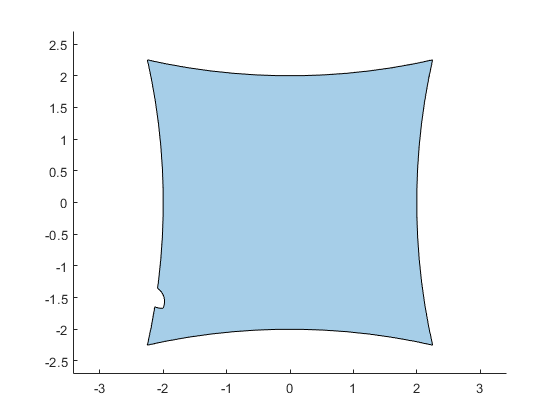

% figure();
% plot(spot)
% axis equal

spotOnCushion = subtract(cushion, spot);
figure();
plot(spotOnCushion)
axis equal

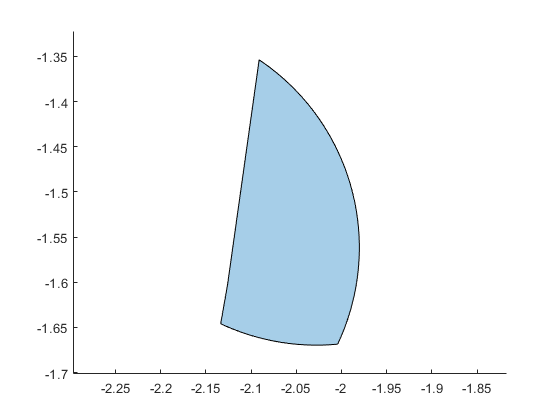


onlySpotOnCushion = intersect(cushion, spot);
figure();
plot(onlySpotOnCushion)
axis equal


Area = area(onlySpotOnCushion)

Area = 0.0335

[x,y] = centroid(onlySpotOnCushion)

x = -2.0548

y = -1.5379